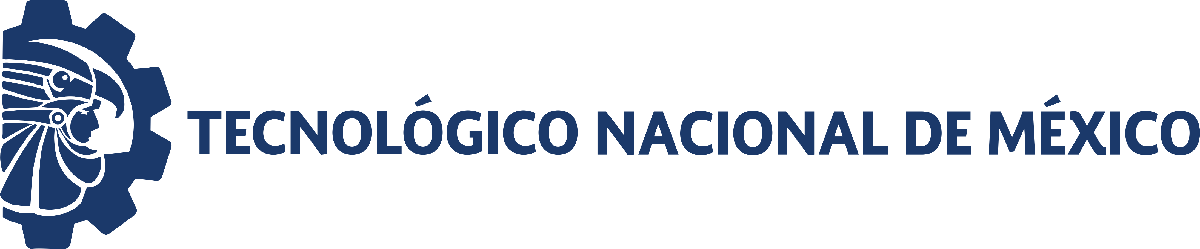                                 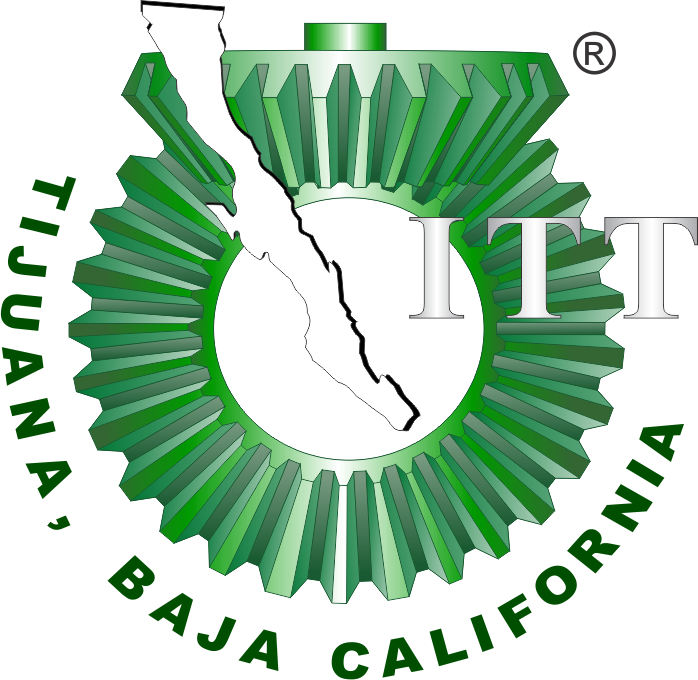

# Práctica cero: Sistema Respiratorio 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información generalhttps:

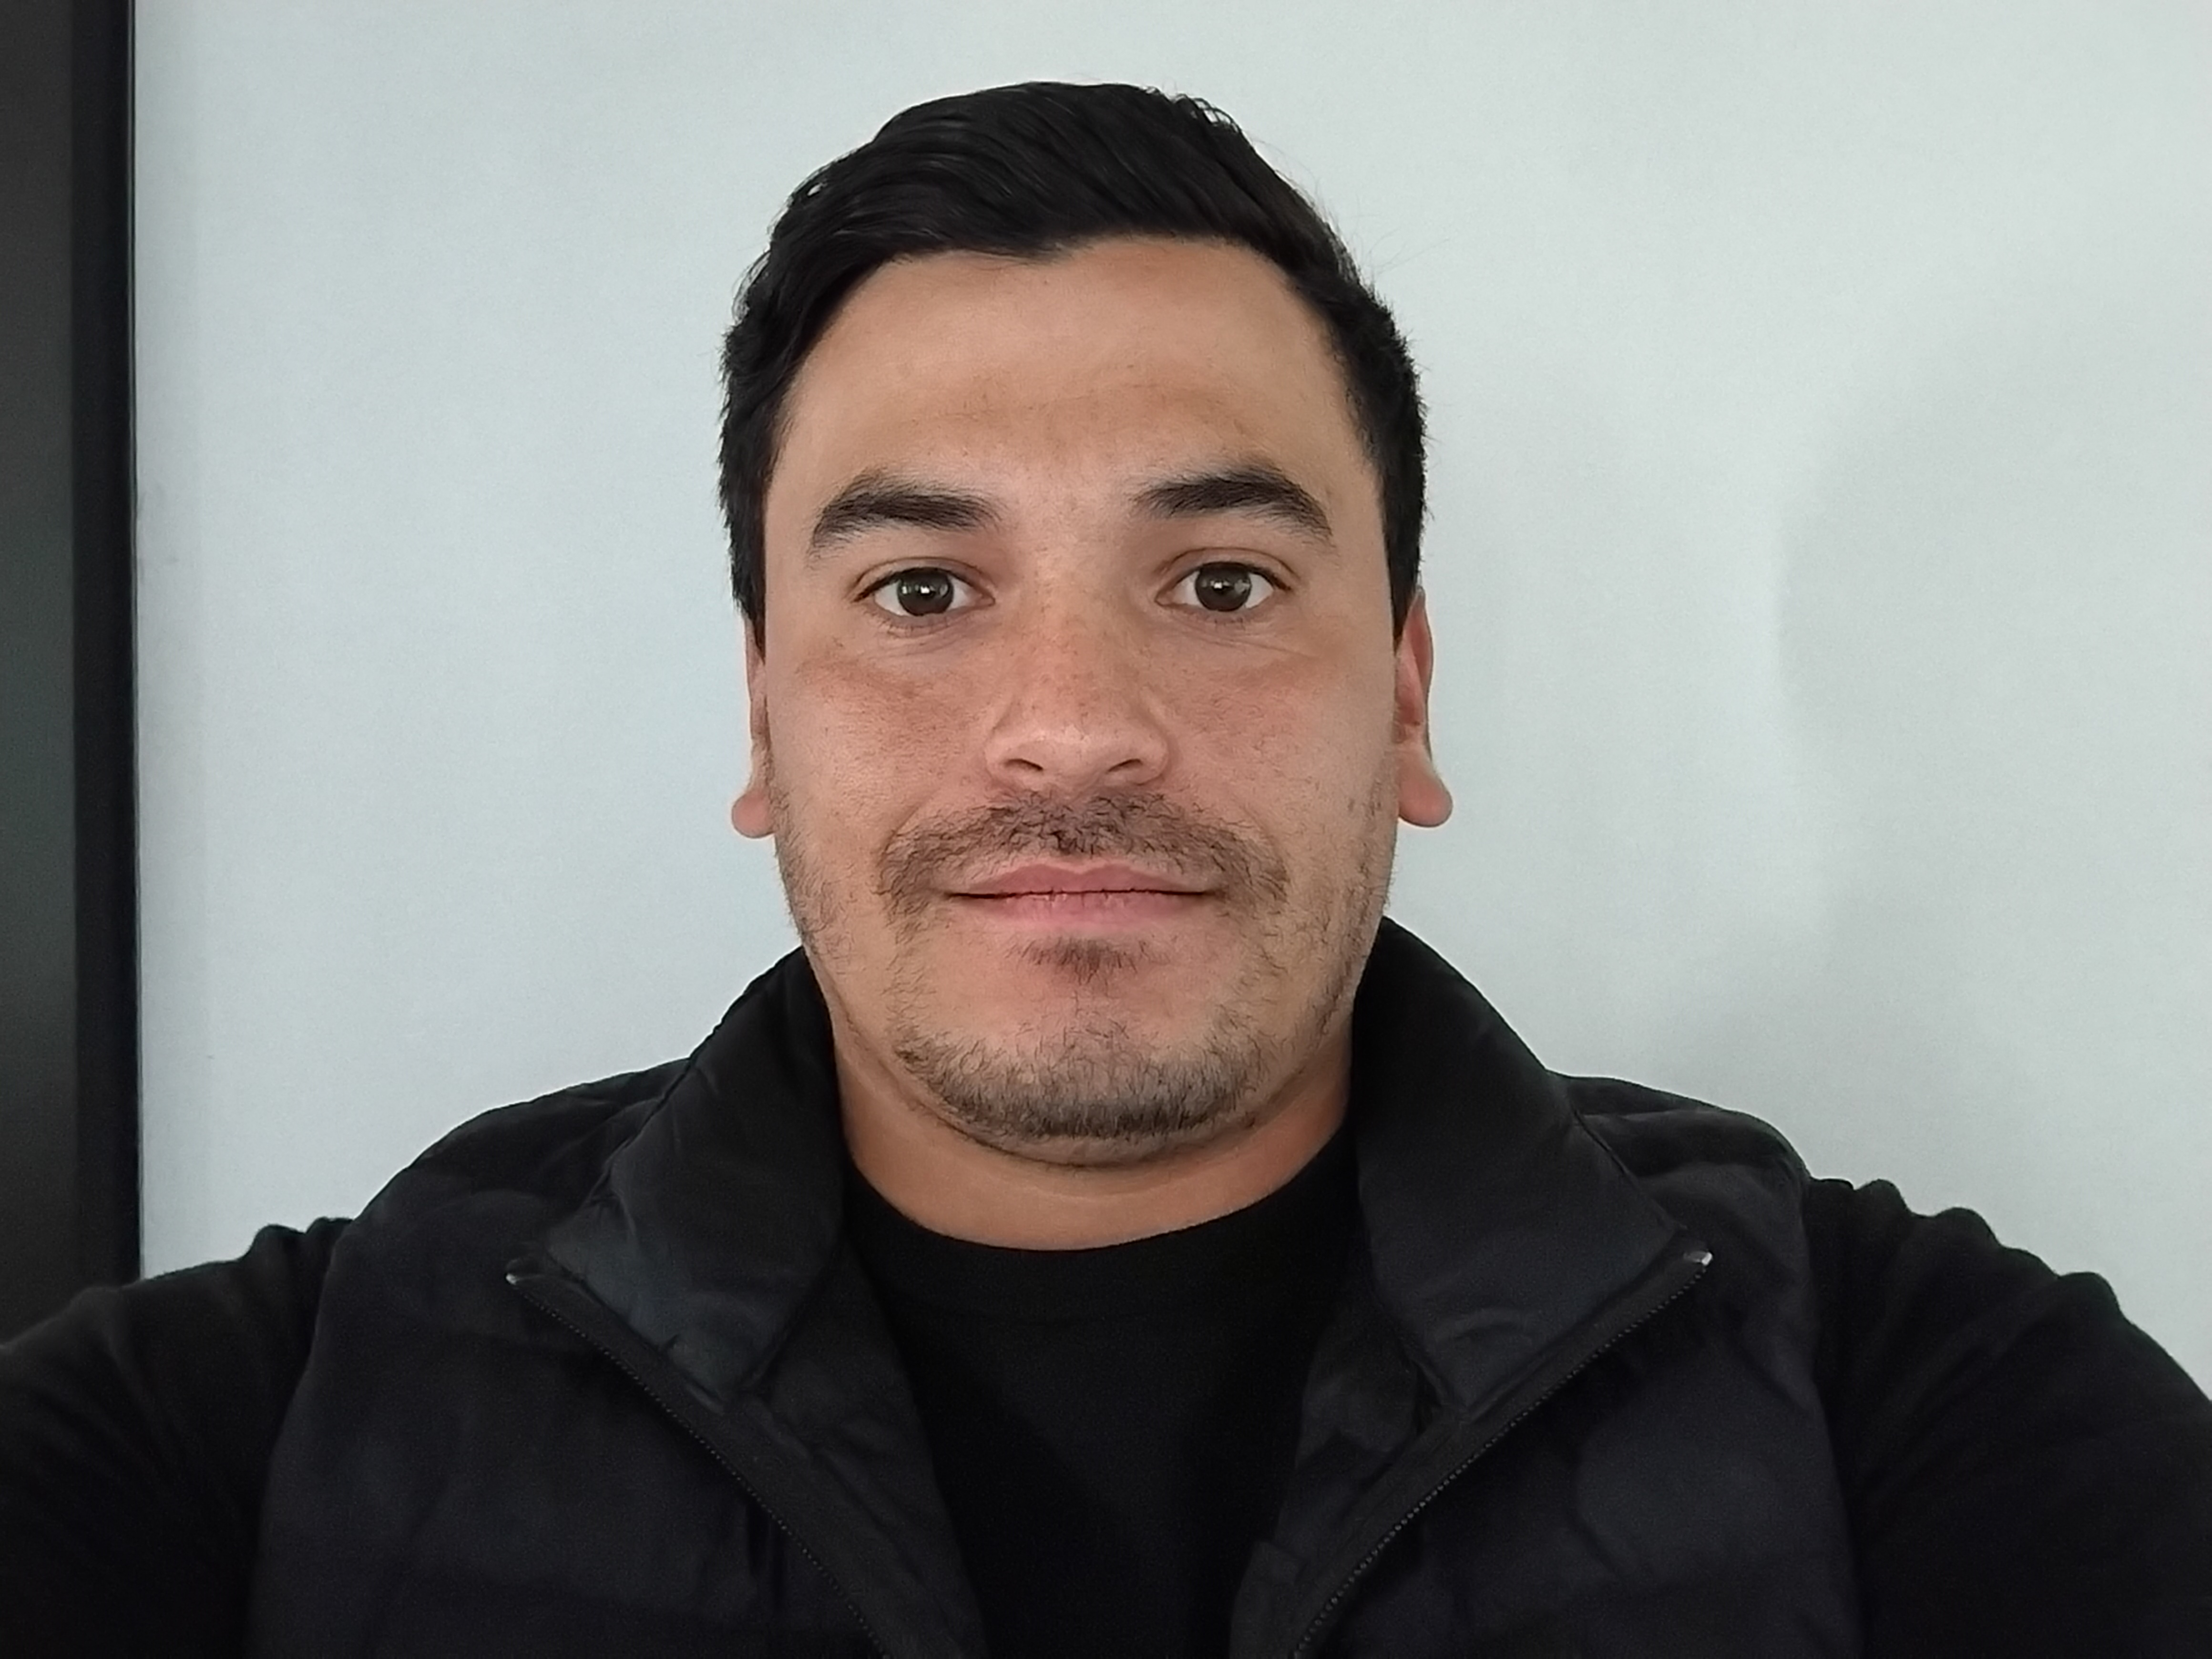

Nombre del alumno: Alan Omar Garcia Toledo

Número de control: 20210787

Correo institucional:** alan.garciat201@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend= '10';
file= 'Resp.slx';
open_system(file);
parameters.StopTime= tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
parameters.StopTime = '30';



Rendimiento del controlador

kP =1511.4945

kl =74979.6737

KD =7.0888

N = 161151.0351

Settling time =0.0216

Overshoot =2.61%

Peak =1.03

**Respiracion Normal **

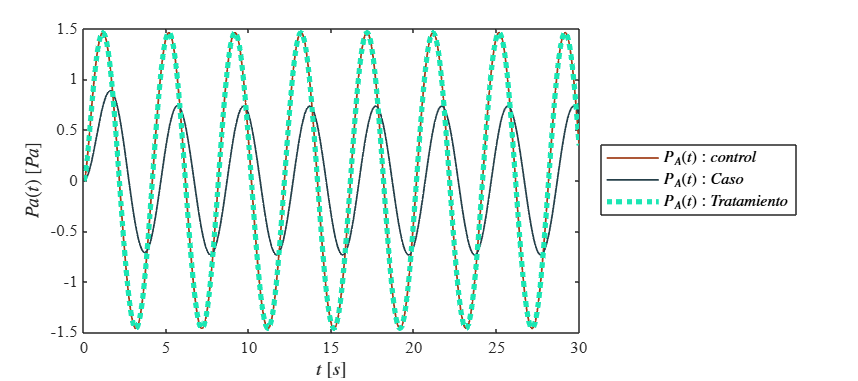

Signal = 'Respiracion normal';
set_param('Resp/Pao(t)','sw','0');
set_param('Resp/PID Controller','P','1511.4945');
set_param('Resp/PID Controller','I','74979.6737');
set_param('Resp/PID Controller','D','7.0888');
N = sim(file,parameters);
plotsignals(N.t,N.PAx,N.PAy,N.PAz,Signal)

**Respiracion Anormal **

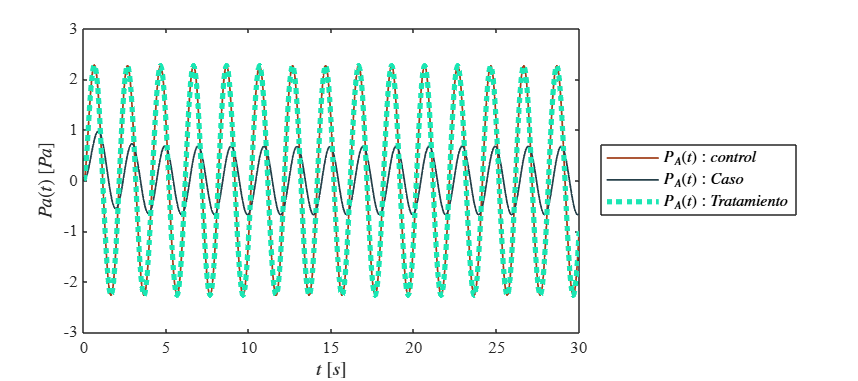

Signal = 'Respiracion anormal';
set_param('Resp/Pao(t)','sw','1');
set_param('Resp/PID Controller','P','1511.4945');
set_param('Resp/PID Controller','I','74979.6737');
set_param('Resp/PID Controller','D','7.0888');
N = sim(file,parameters);
plotsignals(N.t,N.PAx,N.PAy,N.PAz,Signal)

**Funcion : Respuesta a las señales**

function plotsignals (t,PA,Pao,PID,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','Centimeters','Position',[1,1,18,8])
    set(gca,'FontName','Times New Roman')
    fontsize(10,'points')
    %Color 1 naranja [0.15,0.25,0.29]
    %Color 2 morado [0.5,0.3,0.2]
    %Color 3 azul [0.63,0.25,0.11]
    %Color 4 rojo [0.1,0.9,0.7]
    na1 =  [0.15,0.25,0.29];
    mor1 = [0.5,0.3,0.2]; 
    azu1 = [0.63,0.25,0.11];
    roj1 = [0.1,0.9,0.7];
    hold on ; grid off; box on

    plot(t,PA,'LineWidth',1,'Color',azu1)
    plot(t,Pao,'LineWidth',1,'Color',na1)
    plot(t,PID,':','LineWidth',3,'Color',roj1)

    xlabel('$t$ $[s]$','Interpreter','Latex')
    ylabel('$Pa(t)$ $[Pa]$','Interpreter','Latex')

    L = legend('$P_{A}(t): control$','$P_A(t): Caso$','$P_{A}(t): Tratamiento$');
    set(L,'Interpreter','Latex','Location','EastOutside','Box','on')

   
end
